# Simple example of a layer containing domains using a custom XY model

Domains custom XY models operate in the same way as custom layer models, in that there is an additional input to the custom model specifying the domain to be calculated....

 

This is then used within the function to calculate the correct SLD profile for each contrast and domain.

In this example, we simulate a hydrogenated layer on a silicon substrate, containing domains of a larger SLD, against D2O, SMW and water.

Start by making the project and adding the parameters..

problem = createProject(calcType="domains");
problem.setModelType('custom XY');
problem.setGeometry('substrate/liquid');

% Make some parameters...
params = {{'Oxide thick',   10,         20,         50,     true}
          {'Layer thick',   1,          30,         500,    true}
          {'Layer SLD',     -0.5e-6,    -0.5e-6     0,      true}
          {'Layer rough',   2,          5,          7,      true}
          {'Domain rho ',   1e-6,       1e-6,       5e-6,   true}};

problem.addParameterGroup(params);

..and set the SLD's of the bulk phases for our samples.


% Set the bulk SLD
problem.setBulkIn(1,'name','Silicon','Value',2.073e-6,'max',2.073e-6,'fit',false);

% Add another couple of bulk-out's 
problem.addBulkOut('SLD SMW', 2e-6, 2.073e-6, 2.1e-6);
problem.addBulkOut('SLD H2O', -0.6e-6, -0.56e-6, -0.5e-6);

% and modify scalefactor for Solid / Liquid ...
problem.setScalefactor(1,'min',0.8,'Value',1,'max',1.1,'fit',true);


The custom file takes the parameters and build the model as usual, changing the SLD of the layer depending on whether we are calculating the layer (domain = 1), or the domain (domain = 2).

type domainsXY

function [SLD, subRough] = domainsXY(params,bulk_in,bulk_out,contrast,domain)

debugPlot = false;      % optional debug plot

% Split up the parameters for convenience...
subRough = params(1);
oxideThick = params(2);
layerThick = params(3);
layerSLD = params(4);
layerRough = params(5);
domainSLD = params(6);

% Make an array of z values for our model...
z = 0:1:140;

% Make the volume fraction distribution for our Silicon substrate....
[vfSilicon, siSurf] = makeLayer(z,-25,50,1,subRough,subRough);

% ..and the Oxide....
[vfOxide, oxSurface] = makeLayer(z,siSurf,oxideThick,1,subRough,subRough);

% ..also our layer.
[vfLayer, laySurface] = makeLayer(z,oxSurface,layerThick,1,subRough,layerRough);

% Evereything that is not already occupied will be filled will water..
totalVF = vfSilicon + vfOxide + vfLayer;
vfWater = 1 - totalVF;

% Now convert the Volume Fractions to SLD's...
siSLD = vfSilicon * bulk_in;
oxSLD = vfOxide * 3.41e-6;

% Layer SLD depends on whether we are calculating the do

Finally, add the custom file to the project, and make our three contrasts..

% Add the custom file...
problem.addCustomFile('Domain Layer','domainsXY.m','matlab','examples/domains/customXY');

% Make a contrast
problem.addContrast('name',         'D2O',...
                    'background',   'Background 1',...
                    'resolution',   'Resolution 1',...
                    'scalefactor',  'Scalefactor 1',...
                    'Bulkin',       'Silicon',...       
                    'Bulkout',      'SLD D2O',....           
                    'domainRatio',  'Domain Ratio 1',...
                    'data',         'Simulation');

problem.addContrast('name',         'SMW',...
                    'background',   'Background 1',...
                    'resolution',   'Resolution 1',...
                    'scalefactor',  'Scalefactor 1',...
                    'Bulkin',       'Silicon',...       
                    'Bulkout',      'SLD SMW',....           
                    'domainRatio',  'Domain Ratio 1',...
                    'data',         'Simulation');

problem.addContrast('name',         'H2O',...
                    'background',   'Background 1',...
                    'resolution',   'Resolution 1',...
                    'scalefactor',  'Scalefactor 1',...
                    'Bulkin',       'Silicon',...       
                    'Bulkout',      'SLD H2O',....           
                    'domainRatio',  'Domain Ratio 1',...
                    'data',         'Simulation');

% Set the model to our custom file...
for i = 1:3
    problem.setContrastModel(i,'Domain Layer');
end

Finally, run the simulation and plot the results....

controls = controlsClass();

[problem, results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________

Elapsed time is 0.027021 seconds.

Finished RAT ______________________________________________________________________________________________ 



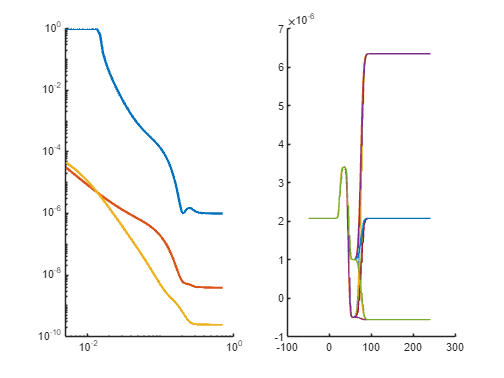


plotRefSLD(problem,results);